[cities, best_tour] = read_tsp();
D = pdist(cities);
Z = squareform(D);
best_length = tour_length(Z, best_tour);

tours = zeros([100, 100]);
for i = 1:100
    tours(:, i) = randperm(100)';
end

[tour, length, lengths] = find_best_tour(Z, tours);
%for ii = 1:10
iteration = 0;
while length >= 20751*1.1
%for p = 1:4000
    N = randi([1, 100]);
    for i = 1:N
        strategy = randi([1 8]);
        a = randsample(100, 1, true, lengths/norm(lengths));
        b = randsample(100, 1, true, lengths/norm(lengths));
        switch strategy
            case 1 
                tours = [tours inversion_mutation(tours(:, a))];
            case 2
                tours = [tours insertion_mutation(tours(:, a))];
            case 3 
                tours = [tours displacement_mutation(tours(:, a))];
            case 4 
                tours = [tours swap_mutation(tours(:, a))];
            case 5 
                tours = [tours OBX(tours(:, a), tours(:, b))];
            case 6
                tours = [tours OX(tours(:, a), tours(:, b))];
            case 7 
                tours = [tours PBX(tours(:, a), tours(:, b))];
            case 8 
                tours = [tours SEC(tours(:, a), tours(:, b))];
        end
    end  
    iteration = iteration + 1;
    tours = find_best_tour(Z, tours, 100);
    [tour, length, lengths] = find_best_tour(Z, tours);
end

fprintf("total iteration: %d\n", iteration);

total iteration: 2957


tour_length(Z, tour)

ans =      2.277778453815124e+04


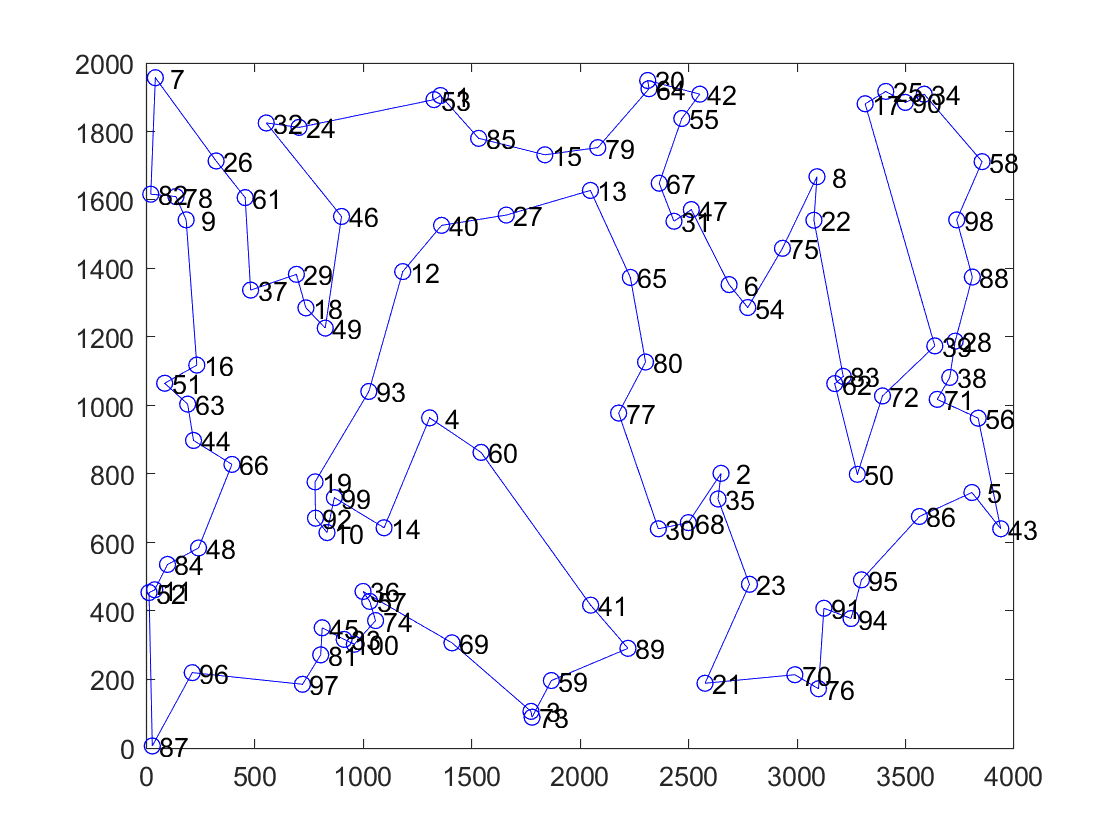

plot_tour(cities, tour)